clear all;

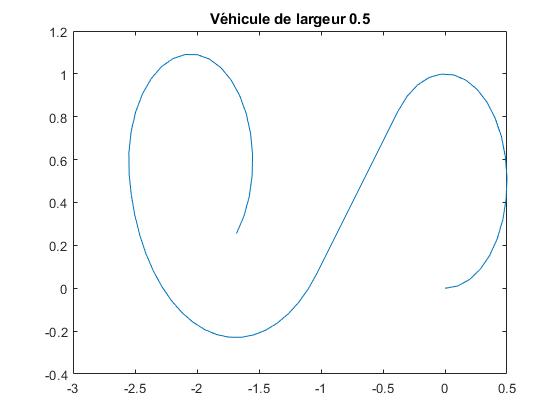

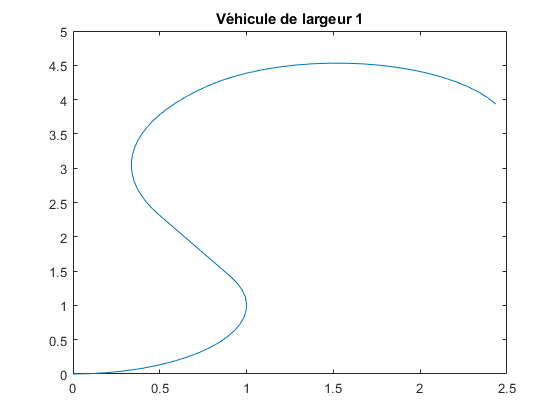

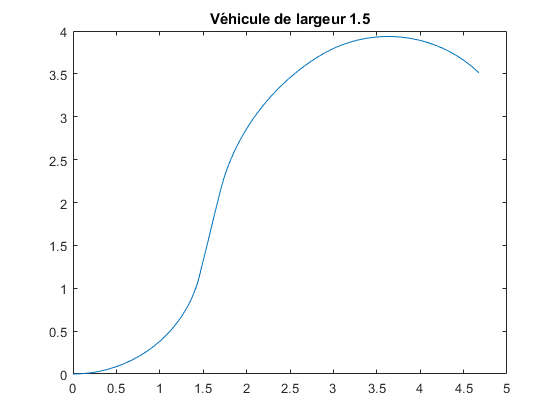

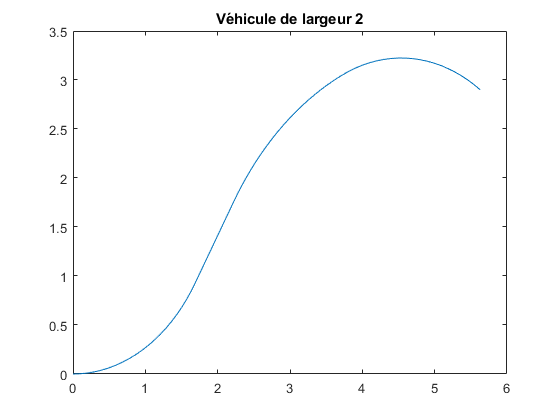

for i = 0.5:0.5:2
    kinematicModel = bicycleKinematics("WheelBase", i);
    initialState = [0 0 0];
    tspan = 0:0.05:1; % Simul 1s, timestep 0.05s
    
    inputs = [2 pi/4]; % Commande 2 m/s | Tourne à gauche (roue à pi/4)
    %Simuler mouvement 
    [t,y] = ode45(@(t,y)derivative(kinematicModel,y,inputs),tspan,initialState);
    inputs = [1 0]; % Commande 2 m/s | Tourne à gauche (roue à pi/4)
    
    %Simuler mouvement
    [t,y2] = ode45(@(t,y2)derivative(kinematicModel,y2,inputs),tspan,y(21,:));
    y_fin = [y; y2];
    
    inputs = [2 -pi/6]; % Commande 2 m/s | Tourne à gauche (roue à pi/4)
    %Simuler mouvement
    [t,y2] = ode45(@(t,y2)derivative(kinematicModel,y2,inputs),tspan,y_fin(42,:));
    y_fin = [y_fin; y2];
    
    inputs = [2 -pi/4]; % Commande 2 m/s | Tourne à gauche (roue à pi/4)
    %Simuler mouvement
    [t,y2] = ode45(@(t,y2)derivative(kinematicModel,y2,inputs),tspan,y_fin(63,:));
    y_fin = [y_fin; y2];
    figure
    plot(y_fin(:,1),y_fin(:,2))
    title(sprintf("Véhicule de largeur %g", i))
end